clear, warning off

% Export data? Then make this = 1
write_matrices = 1;

% Load flux balance
phi1 = 0.003;
phi2 = 0.018;
efficiency = 0.95;

V = Parameters_flux_balance(phi1,phi2,efficiency);

% Set metabolite concentrations in glycolytic growth
% F6P  FBP   PEP   TCA
S0 = [1 1 1 1]; 
S0norm = S0;

% Set Km values
%        PFK  FBPase  PYK     gng^low
Km   =  [2 .05 1 5];

% Relative Km's
KmN  = Km./[S0(1) S0(2) S0(3) S0(4)];

% Compound parameters V = k_cat*phi
% PFK(2)  FBPase(3) PYK(4) gng^low(5)          
ixt       = [2 3 4 5];
V(ixt) = (1+KmN).*V(ixt);  

%% Allosteric interaction parameters
alphas = [ .5 3 .95 0];

%% Constants that define glycolytic/gluconeogenic enzymes
GLYconstants = [.3 .6  V(2) V(4)];
GNGconstants = [7 7 V(3) V(5) ];

% % Test for trade-off figure
% gamma = 0.3;
% V(4) = 0.7*V(4);
% V(3) = 1/gamma*V(3);
% GLYconstants(4)=V(4);
% GNGconstants(3)=V(3);


% Define shift
shifts.time = [0.01 10 30 50];
shifts.glc = [1 0 1 0];
shifts.ace = [0 1 0 0];

% Run model
[modelObj,simData] = Model(V,KmN,S0,S0norm,alphas,GNGconstants,GLYconstants,shifts);

% Load parameters and results of simulation
createParameters(modelObj,simData);
time = simData.time/3600; % Change time units from seconds to hours
gly_to_gng = shifts.time(2)*60;
gng_to_gly = shifts.time(3)*60;
Gr = 0.9/0.62*kBM.*(F6P/F6Pnorm).*(PEP/PEPnorm).*(PYR/PYRnorm); % 0.62mM/s flux gives gr 0.9/h


## Figure 1 Enzyme abundance and metabolite concentrations

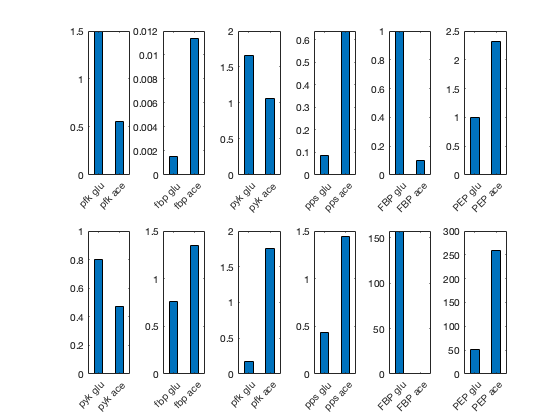

figure,
subplot(2,6,1)
pfk_ss = [pfk(gly_to_gng-1), pfk(gng_to_gly-1)];
labels_pfk = categorical({'pfk glu'; 'pfk ace'});
labels_pfk = reordercats(labels_pfk,[2 1]);
bar (labels_pfk,pfk_ss,.4)



subplot(2,6,2)
fbp_ss = [fbpase(gly_to_gng-1), fbpase(gng_to_gly-1)];
labels_fbp = categorical({'fbp glu'; 'fbp ace'});
labels_fbp = reordercats(labels_fbp,[2 1]);
bar (labels_fbp,fbp_ss,.4)


subplot(2,6,3)
pyk_ss = [pyk(gly_to_gng-1), pyk(gng_to_gly-1)];
labels_pyk = categorical({'pyk glu'; 'pyk ace'});
labels_pyk = reordercats(labels_pyk,[2 1]);
bar (labels_pyk,pyk_ss,.4)


subplot(2,6,4)
pps_ss = [pps(gly_to_gng-1), pps(gng_to_gly-1)];
labels_pps = categorical({'pps glu'; 'pps ace'});
labels_pps = reordercats(labels_pps,[2 1]);
bar (labels_pps,pps_ss,.4)


subplot(2,6,5)
FBP_ss = [FBP(gly_to_gng-1), FBP(gng_to_gly-1)];
labels_FBP = categorical({'FBP glu'; 'FBP ace'});
labels_FBP = reordercats(labels_FBP,[2 1]);
bar (labels_FBP,FBP_ss,.4)


subplot(2,6,6)
PEP_ss = [PEP(gly_to_gng-1), PEP(gng_to_gly-1)];
labels_PEP = categorical({'PEP glu'; 'PEP ace'});
labels_PEP = reordercats(labels_PEP,[2 1]);
bar (labels_PEP,PEP_ss,.4)

% Save steady states
S0_gly = [F6P(gly_to_gng-1) FBP(gly_to_gng-1) PEP(gly_to_gng-1) PYR(gly_to_gng-1)];
S0_gng = [F6P(gng_to_gly-1) FBP(gng_to_gly-1) PEP(gng_to_gly-1) PYR(gng_to_gly-1)];

% Compare to experimental data
subplot(2,6,7),
A=readmatrix('fig2_proteome/pfkA.csv');
bar(labels_pyk,A([4,1]),.4)

subplot(2,6,8),
A=readmatrix('fig2_proteome/fbp.csv');
bar(labels_fbp,A([4,1]),.4)

subplot(2,6,9),
A=readmatrix('fig2_proteome/pckA.csv');
bar(labels_pfk,A([4,1]),.4)

subplot(2,6,10),
A=readmatrix('fig2_proteome/ppsA.csv');
bar(labels_pps,A([4,1]),.4)

subplot(2,6,11),
A=readmatrix('fig2_metabolites/FBP.csv');
bar(labels_FBP,A([2,3]),.4)

subplot(2,6,12),
A=readmatrix('fig2_metabolites/PEP.csv');
bar(labels_PEP,A([2,3]),.4)

## Figure 2 A-F: Glc to GNG 

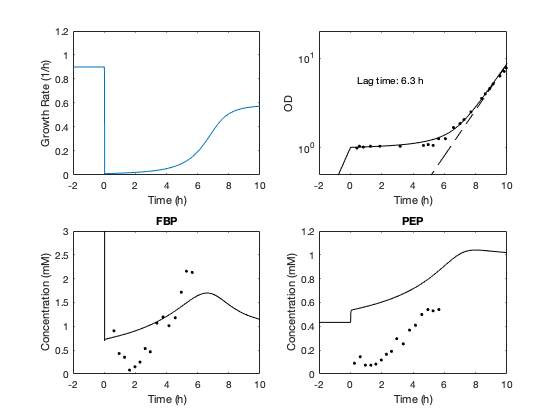

createParameters(modelObj,simData);

OD = exp(cumsum(Gr/60));

figure;
title('Glucose to Acetate');
subplot(2,2,1)
plot(time-time(gly_to_gng),Gr)
ylim([0 1.2])
xlim([-2,10])
xlabel("Time (h)")
ylabel("Growth Rate (1/h)")

subplot(2,2,2)
A=readmatrix('fig4_data/od.csv');
semilogy(time-time(gly_to_gng),OD/OD(gly_to_gng),'-k',A(:,3)/60,A(:,4)/0.045,'k.')
xlabel("Time (h)")
ylabel("OD")
xlim([-2 10])
ylim([0.5 8])


p = polyfit(time(gng_to_gly-100:gng_to_gly)-time(gly_to_gng), log(OD(gng_to_gly-100:gng_to_gly)/OD(gly_to_gng)),1); 
lag_gly_to_gng = -p(2)/p(1); 
text(0.2,.66,['Lag time: ', num2str(lag_gly_to_gng,'%2.1f'), ' h'],'Units','normalized')
hold on
semilogy((0:20),exp(p(2)+p(1)*(0:20)),'k--')
plot([0 10], OD(gly_to_gng)*[1 1],'k--')

xlim([-2, 10])
ylim([.5 20])
subplot(2,2,3),
A=readmatrix('fig4_data/FBP.csv');
plot(time-time(gly_to_gng),FBP/FBP(gng_to_gly-1),'-k',A(:,1),A(:,2),'.k')
title("FBP")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 3])
xlim([-2 10])


subplot(2,2,4),
A=readmatrix('fig4_data/PEP.csv');
plot(time-time(gly_to_gng),PEP/PEP(gng_to_gly-1),'-k',A(:,1),A(:,2),'.k')
title("PEP")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 1.2])
xlim([-2 10])

## Figure 2 G-J: GNG to GLY

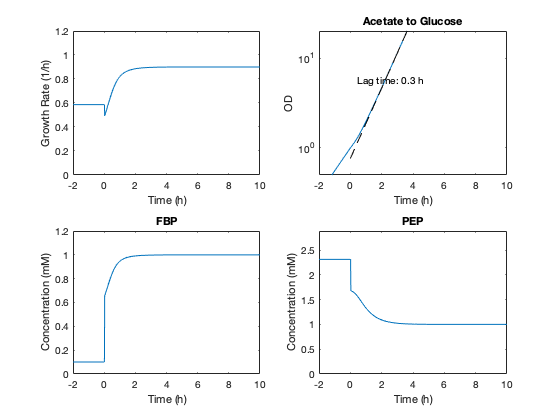

figure,
title('Acetate to Glucose');
subplot(2,2,1)
plot(time-time(gng_to_gly),Gr)
ylim([0 1.2])
xlim([-2,10])
xlabel("Time (h)")
ylabel("Growth Rate (1/h)")


subplot(2,2,2)
semilogy(time-time(gng_to_gly),OD/OD(gng_to_gly))
title('Acetate to Glucose');
xlabel("Time (h)")
ylabel("OD")

p = polyfit(time(end-100:end)-time(gng_to_gly), log(OD(end-100:end) / OD(gng_to_gly)),1); 
lag_gng_to_gly = -p(2)/p(1); 
text(0.2,.66,['Lag time: ', num2str(lag_gng_to_gly,'%2.1f'), ' h'],'Units','normalized')
hold on
semilogy((0:20),exp(p(2)+p(1)*(0:20)),'k--')
plot([0 20], OD(gng_to_gly)*[1 1],'k--')
xlim([-2, 10])
ylim([.5 20])

subplot(2,2,3),plot(time-time(gng_to_gly),FBP)
title("FBP")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 max(FBP)*1.2])
xlim([-2 10])


subplot(2,2,4),plot(time-time(gng_to_gly),PEP)
title("PEP")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 max(PEP)*1.2])
xlim([-2 10])

## Fig. S2 Enzyme abundance

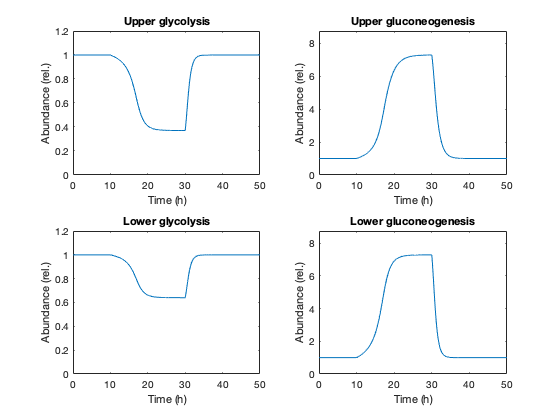

figure;
subplot(2,2,1),plot(time,pfk/pfk(1))
title("Upper glycolysis")
xlabel("Time (h)")
ylabel("Abundance (rel.)")
ylim([0 1.2])

subplot(2,2,2),plot(time,fbpase/fbpase(1))
title("Upper gluconeogenesis")
xlabel("Time (h)")
ylabel("Abundance (rel.)")
ylim([0 1.2*max(fbpase)/fbpase(1)])

subplot(2,2,3),plot(time,pyk/pyk(1))
title("Lower glycolysis")
xlabel("Time (h)")
ylabel("Abundance (rel.)")
ylim([0 1.2])

subplot(2,2,4),plot(time,pps/pps(1))
title("Lower gluconeogenesis")
xlabel("Time (h)")
ylabel("Abundance (rel.)")
ylim([0 1.2*max(pps)/pps(1)])

saveas(gcf,'figures/enzymes.pdf')

## Fig. S4 Enzyme regulation

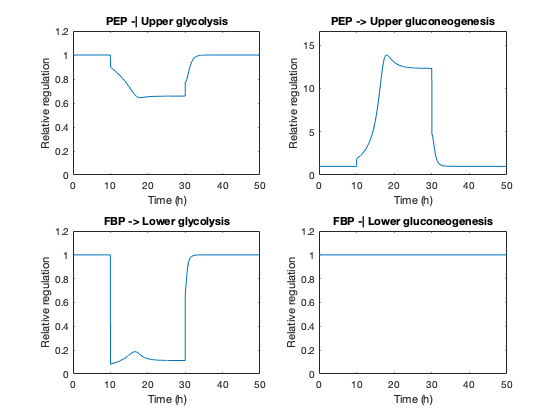

figure;
subplot(2,2,1),plot(time,(PEP/PEPnorm).^(-pfkPEPalpha))
title("PEP -| Upper glycolysis")
xlabel("Time (h)")
ylabel("Relative regulation")
ylim([0 max((PEP/PEPnorm).^(-pfkPEPalpha))*1.2])

subplot(2,2,2),plot(time,(PEP/PEPnorm).^(fbpasePEPalpha))
title("PEP -> Upper gluconeogenesis")
xlabel("Time (h)")
ylabel("Relative regulation")
ylim([0 max((PEP/PEPnorm).^(fbpasePEPalpha))*1.2])

subplot(2,2,3),plot(time,(FBP/FBPnorm).^pykFBPalpha)
title("FBP -> Lower glycolysis")
xlabel("Time (h)")
ylabel("Relative regulation")
ylim([0 max((FBP/FBPnorm).^pykFBPalpha)*1.2])

subplot(2,2,4),plot(time,(FBP/FBPnorm).^(-ppsFBPalpha))
title("FBP -| Lower gluconeogenesis")
xlabel("Time (h)")
ylabel("Relative regulation")
ylim([0 max((FBP/FBPnorm).^(-ppsFBPalpha))*1.2])

saveas(gcf,'figures/allosteric_regulation.pdf')

## Fig. S3 Metabolite levels

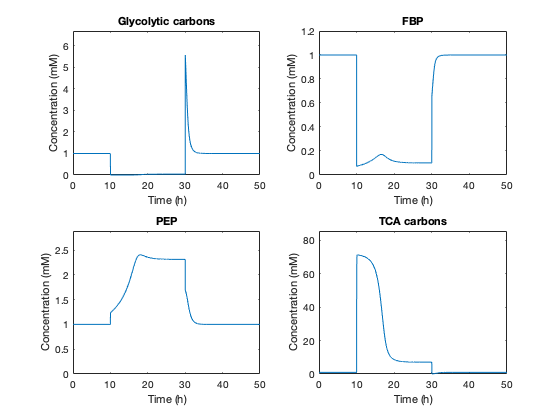

figure;
subplot(2,2,1),plot(time,F6P)
title("Glycolytic carbons")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 max(F6P)*1.2])

subplot(2,2,2),plot(time,FBP)
title("FBP")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 max(FBP)*1.2])

subplot(2,2,3),plot(time,PEP)
title("PEP")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 max(PEP)*1.2])

subplot(2,2,4),plot(time,PYR)
title("TCA carbons")
xlabel("Time (h)")
ylabel("Concentration (mM)")
ylim([0 max(PYR)*1.2])

saveas(gcf,'figures/metabolite_concentrations.pdf')

## Fig. S5 Enzyme saturation

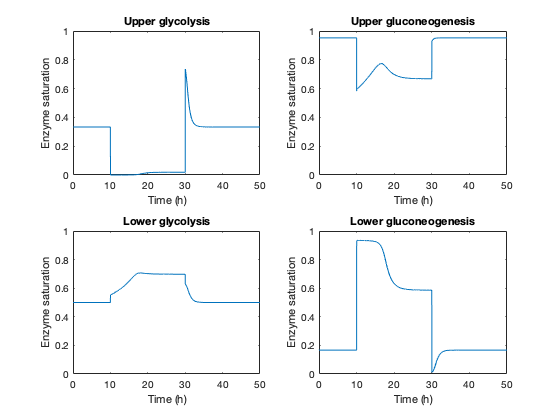

figure;
subplot(2,2,1),plot(time,(F6P/F6Pnorm)./(KmPFK + F6P/F6Pnorm))
title("Upper glycolysis")
xlabel("Time (h)")
ylabel("Enzyme saturation")
ylim([0 1])

subplot(2,2,2),plot(time,(FBP/FBPnorm)./(KmFBP + FBP/FBPnorm))
title("Upper gluconeogenesis")
xlabel("Time (h)")
ylabel("Enzyme saturation")
ylim([0 1])

subplot(2,2,3),plot(time,(PEP/PEPnorm)./(KmPYK + (PEP/PEPnorm)))
title("Lower glycolysis")
xlabel("Time (h)")
ylabel("Enzyme saturation")
ylim([0 1])

subplot(2,2,4),plot(time,(PYR/PYRnorm)./(KmPPS + (PYR/PYRnorm)))
title("Lower gluconeogenesis")
xlabel("Time (h)")
ylabel("Enzyme saturation")
ylim([0 1])

saveas(gcf,'figures/enzyme_saturation.pdf')

## Fig. S6 Fluxes

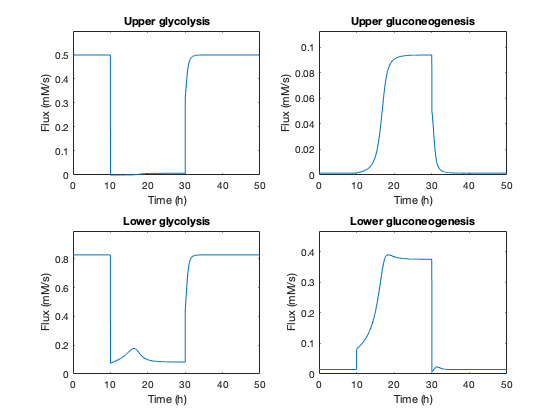

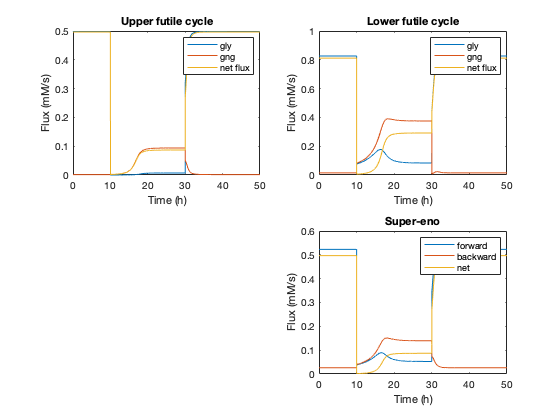

figure;
pfk_flux = pfk.*((PEP/PEPnorm).^(-pfkPEPalpha)).*(F6P/F6Pnorm)./(KmPFK + F6P/F6Pnorm);
subplot(2,2,1),plot(time,pfk_flux)
title("Upper glycolysis")
xlabel("Time (h)")
ylabel("Flux (mM/s)")
ylim([0 max(pfk_flux)*1.2])

fbp_flux = fbpase.*((PEP/PEPnorm).^(fbpasePEPalpha)).*(FBP/FBPnorm)./(KmFBP + FBP/FBPnorm);
subplot(2,2,2),plot(time,fbp_flux)
title("Upper gluconeogenesis")
xlabel("Time (h)")
ylabel("Flux (mM/s)")
ylim([0 max(fbp_flux)*1.2])

pyk_flux = pyk.*((FBP/FBPnorm).^pykFBPalpha).*(PEP/PEPnorm)./(KmPYK + (PEP/PEPnorm));
subplot(2,2,3),plot(time,pyk_flux)
title("Lower glycolysis")
xlabel("Time (h)")
ylabel("Flux (mM/s)")
ylim([0 max(pyk_flux)*1.2])

pps_flux = pps.*((FBP/FBPnorm).^(-ppsFBPalpha).*PYR/PYRnorm)./(KmPPS + (PYR/PYRnorm));
subplot(2,2,4),plot(time,pps_flux)
title("Lower gluconeogenesis")
xlabel("Time (h)")
ylabel("Flux (mM/s)")
ylim([0 max(pps_flux)*1.2])
figure;
Upper_futile_flux = abs((pfk_flux-fbp_flux));
subplot(2,2,1),plot(time,[pfk_flux,fbp_flux,Upper_futile_flux])
title("Upper futile cycle")
legend("gly","gng","net flux")
xlabel("Time (h)")
ylabel("Flux (mM/s)")


Lower_futile_flux = abs((pyk_flux-pps_flux));
subplot(2,2,2),plot(time,[pyk_flux,pps_flux,Lower_futile_flux])
title("Lower futile cycle")
legend("gly","gng","net flux")
xlabel("Time (h)")
ylabel("Flux (mM/s)")


subplot(2,2,4),plot(time,[V(8)*(FBP/FBPnorm), V(7)*(PEP/PEPnorm).^2, abs(V(8)*(FBP/FBPnorm)- V(7)*(PEP/PEPnorm).^2)])
title("Super-eno")
legend("forward","backward","net")
xlabel("Time (h)")
ylabel("Flux (mM/s)")
saveas(gcf,'figures/metabolic_fluxes.pdf')

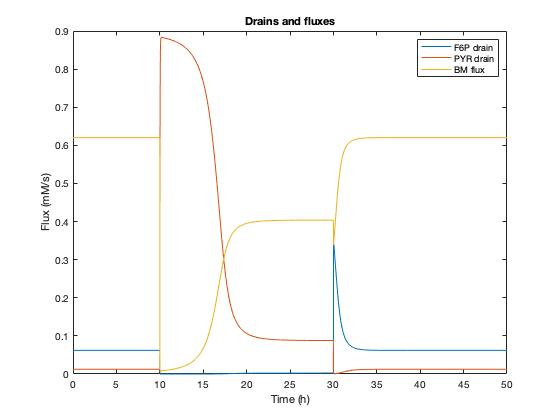


figure;
plot(time,[VmaxF6PDrain.*(F6P./F6Pnorm), VmaxPyrDrain.*(PYR./PYRnorm), kBM.*(F6P./F6Pnorm).*(PEP./PEPnorm).*(PYR./PYRnorm)])
legend("F6P drain","PYR drain","BM flux")
xlabel("Time (h)")
ylabel("Flux (mM/s)")
title("Drains and fluxes")



% Export data

if write_matrices == 1
        
    writematrix(pfk_ss, 'fig2_proteome_th/pfk.csv', "FileType", 'text')
    writematrix(fbp_ss, 'fig2_proteome_th/fbp.csv', "FileType", 'text')
    writematrix(pyk_ss, 'fig2_proteome_th/pyk.csv', "FileType", 'text')
    writematrix(pps_ss, 'fig2_proteome_th/pps.csv', "FileType", 'text')
    writematrix(FBP_ss, 'fig2_metabolites_th/FBP.csv', "FileType", 'text')
    writematrix(PEP_ss, 'fig2_metabolites_th/PEP.csv', "FileType", 'text')

    writematrix([time-time(gly_to_gng),OD/OD(gly_to_gng)], 'fig4_th/od.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),FBP/FBP(gng_to_gly-1)], 'fig4_th/FBP.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),PEP/PEP(gng_to_gly-1)], 'fig4_th/PEP.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),F6P/F6P(gng_to_gly-1)], 'fig4_th/F6P.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),PYR/PYR(gng_to_gly-1)], 'fig4_th/PYR.csv', "FileType", 'text')
    
    writematrix([time-time(gng_to_gly),OD/OD(gng_to_gly)], 'fig4b_th/od.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),PEP/PEP(gng_to_gly-1)], 'fig4b_th/PEP.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),F6P/F6P(gng_to_gly-1)], 'fig4b_th/F6P.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),PYR/PYR(gng_to_gly-1)], 'fig4b_th/PYR.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),FBP/FBP(gng_to_gly-1)], 'fig4b_th/FBP.csv', "FileType", 'text')
    
    writematrix([time-time(gly_to_gng),pyk_flux], 'fig4_th/pyk_flux.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),pfk_flux], 'fig4_th/pfk_flux.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),fbp_flux], 'fig4_th/fbp_flux.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),pps_flux], 'fig4_th/pps_flux.csv', "FileType", 'text')
    writematrix([time-time(gly_to_gng),abs(pfk_flux-fbp_flux),abs(pyk_flux-pps_flux)], 'fig4_th/net_flux.csv', "FileType", 'text')
    
    writematrix([time-time(gng_to_gly),pyk_flux], 'fig4b_th/pyk_flux.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),pfk_flux], 'fig4b_th/pfk_flux.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),fbp_flux], 'fig4b_th/fbp_flux.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),pps_flux], 'fig4b_th/pps_flux.csv', "FileType", 'text')
    writematrix([time-time(gng_to_gly),abs(pfk_flux-fbp_flux),abs(pyk_flux-pps_flux)], 'fig4b_th/net_flux.csv', "FileType", 'text')


end


## Calculate Figure 2 GNG & GLY enzymes, FBP vs growth rate

gr_scan = linspace(0.05,1.2,11);
shifts_scan.time = [0.01 200];
shifts_scan.ace = [0 0];
for n = 1: length(gr_scan)

    shifts_scan.glc = gr_scan(n)/.9*[1 1];
    [modelObj,simData] = Model(V,KmN,S0,S0norm,alphas,GNGconstants,GLYconstants,shifts_scan);
    createParameters(modelObj,simData);
    
    time_scan = simData.time/3600;
    
    FBP_scan(n) = FBP(end);
    PEP_scan(n) = PEP(end);
    
    pfk_scan(n) = pfk(end)/phiBeta_pfk;
    fbp_scan(n) = fbpase(end);
    pyk_scan(n) = pyk(end)/phiBeta_pyk;
    pps_scan(n) = pps(end);

end


## Plot for Fig. S1

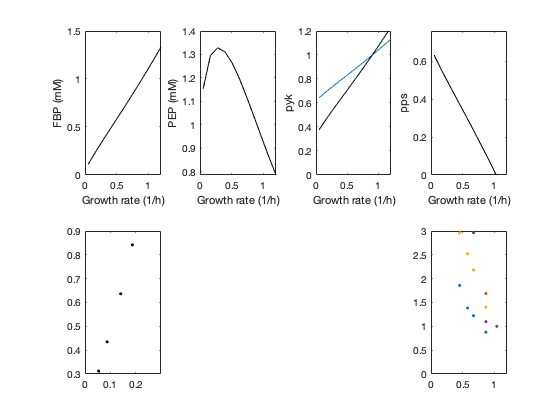

figure,
subplot(2,4,1),
plot(gr_scan,FBP_scan,'-k')
xlabel('Growth rate (1/h)')
ylabel('FBP (mM)')
xlim([0 0.1*round(gr_scan(end)*10)])


subplot(2,4,2),
plot(gr_scan,PEP_scan,'-k')
xlabel('Growth rate (1/h)')
ylabel('PEP (mM)')
xlim([0 0.1*round(gr_scan(end)*10)])


subplot(2,4,3),
plot(gr_scan,pyk_scan,gr_scan,pfk_scan,'-k')
xlabel('Growth rate (1/h)')
ylabel ('pyk')
xlim([0 0.1*round(gr_scan(end)*10)])
ylim([0 1.2])


subplot(2,4,4),
plot(gr_scan,pps_scan,'-k')
xlabel('Growth rate (1/h)')
ylabel('pps')
xlim([0 0.1*round(gr_scan(end)*10)])
ylim([0 pps_scan(1)*1.2])


subplot(2,4,5),
A=readmatrix('fig3_metabolites/Karl_1C.csv');
plot(A(:,1),A(:,2),'k.')
xlim([0 0.3])

subplot(2,4,8),
A=readmatrix('fig3_proteome/prot_gr.csv');
plot(A(:,1),A(:,5),'.',A(:,1),A(:,3),'.',A(:,1),A(:,6),'.',A(:,1),A(:,2),'.')
xlim([0 0.1*round(gr_scan(end)*10)])
ylim([0 3])



if write_matrices == 1


    writematrix([gr_scan', FBP_scan'], 'fig3_metabolites_th/FBP.csv', "FileType", 'text')
    writematrix([gr_scan', PEP_scan'], 'fig3_metabolites_th/PEP.csv', "FileType", 'text')
    writematrix([gr_scan', pyk_scan'], 'fig3_proteome_th/pyk.csv', "FileType", 'text')
    writematrix([gr_scan', pfk_scan'], 'fig3_proteome_th/pfk.csv', "FileType", 'text')
    writematrix([gr_scan', pps_scan'], 'fig3_proteome_th/pps.csv', "FileType", 'text')
    writematrix([gr_scan', fbp_scan'], 'fig3_proteome_th/fbp.csv', "FileType", 'text')

end

% Save workspace variables
save ('main_figures_workspace.mat')


